# Transducer Design

Transducer 1

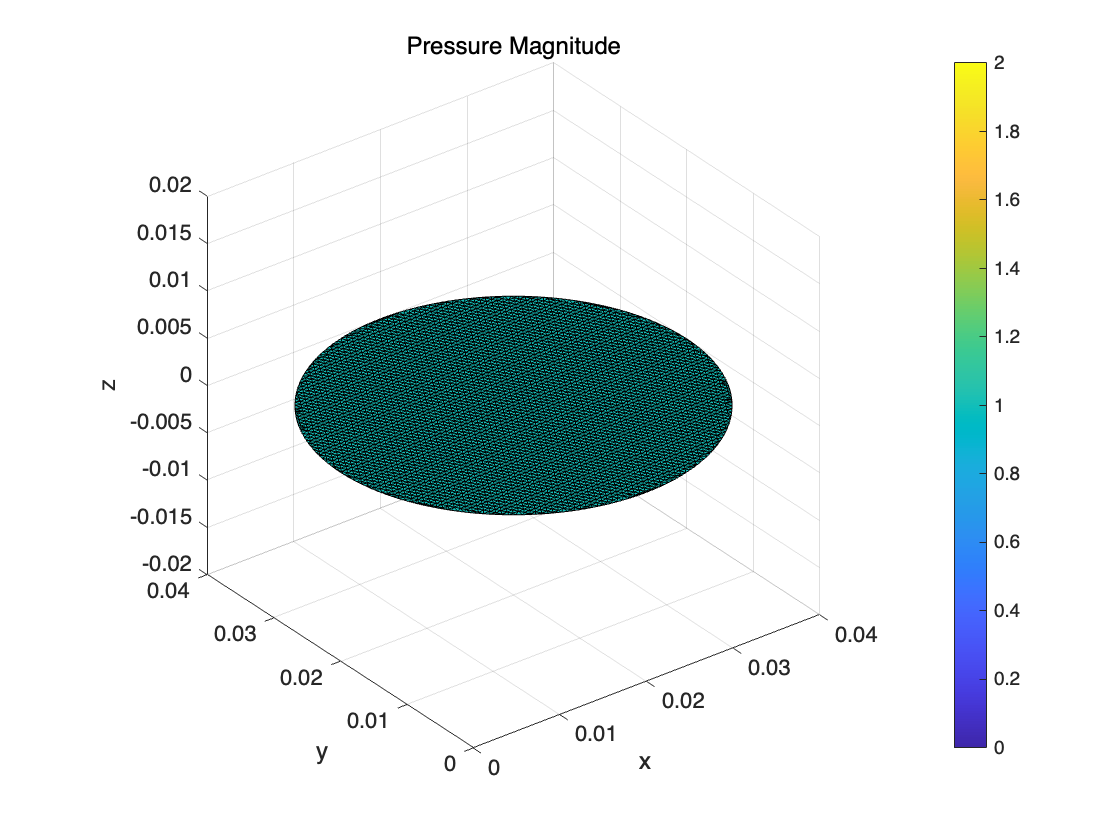

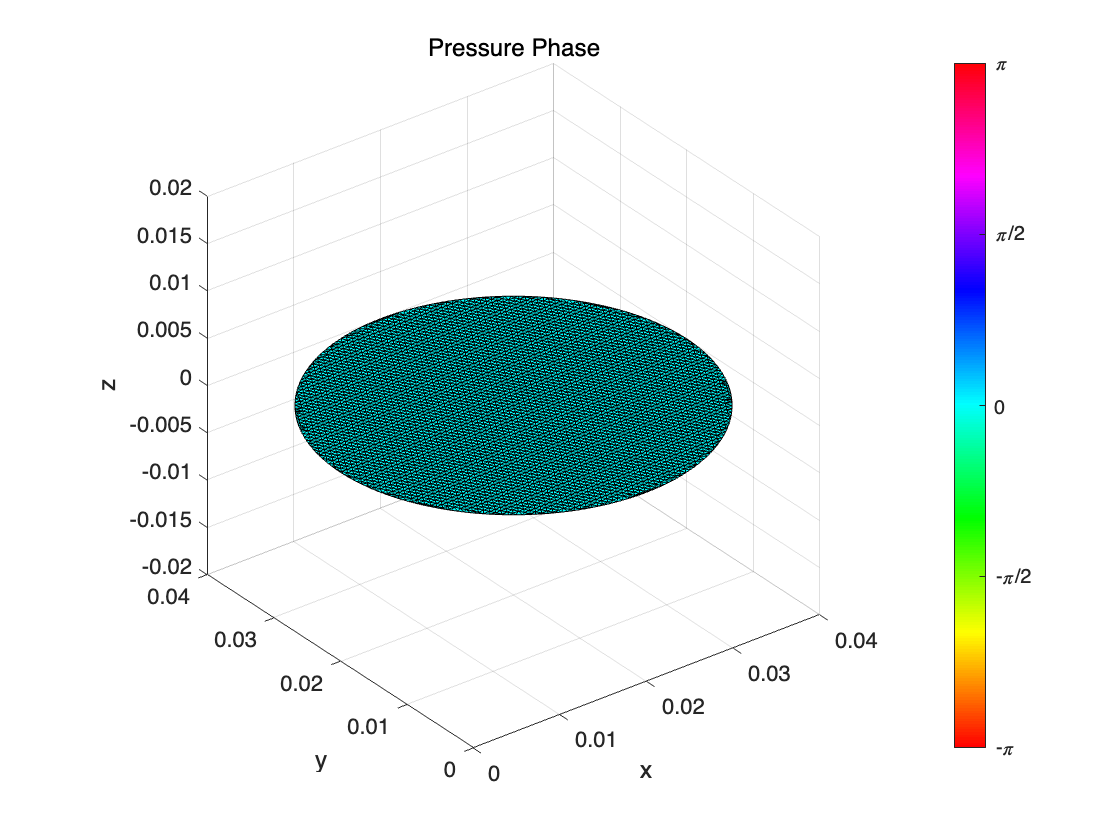

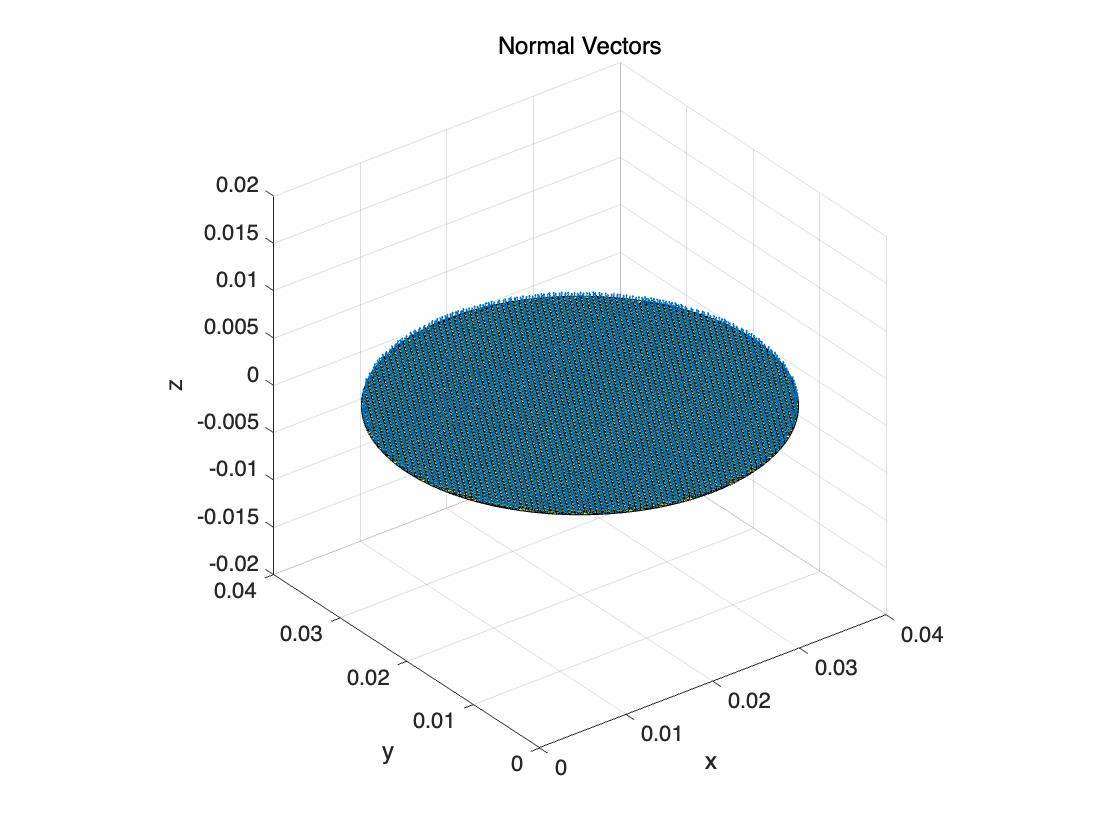

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 1;       % How to set this parameter?
transducer_info.Type = 'circle';
transducer_info.Radius = 2e-2;      
transducer_info.rotate = [0, 0, 0];
transducer_info.medium = 'air';


% Positions and phases for the transducers (1 row)
% positions = [];
% for k = 1:16
%     positions(k) = 0.005 + 0.01 * (k-1);
% end
% PFC_PhaseCalculate(target[x,y], array, focal point z(m))
%phases = PFC_PhaseCalculate([0.08, 0], [1,16], 0.03)

% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
% for i = 1:4
%     for j = 1:4
        % Update position and phase
        transducer_info.position = [0.02,0.02, 0];
        transducer_info.Phase = 0;
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);
        
        % Increment index for next transducer
%         index = index + 1;
%     end
%end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.5e-3 : 40e-3;          % Simulation Area
reading_pos_y = 0 : 0.5e-3 : 40e-3;          % Simulation Area
reading_pos_z = 200e-3 : 0.5e-3 : 400e-3;          % Simulation Area

## Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.02, reading_pos_z);

Started at 2024-05-03 16:02:37
Finished at 2024-05-03 16:03:03
Progressed time : 00:00:26


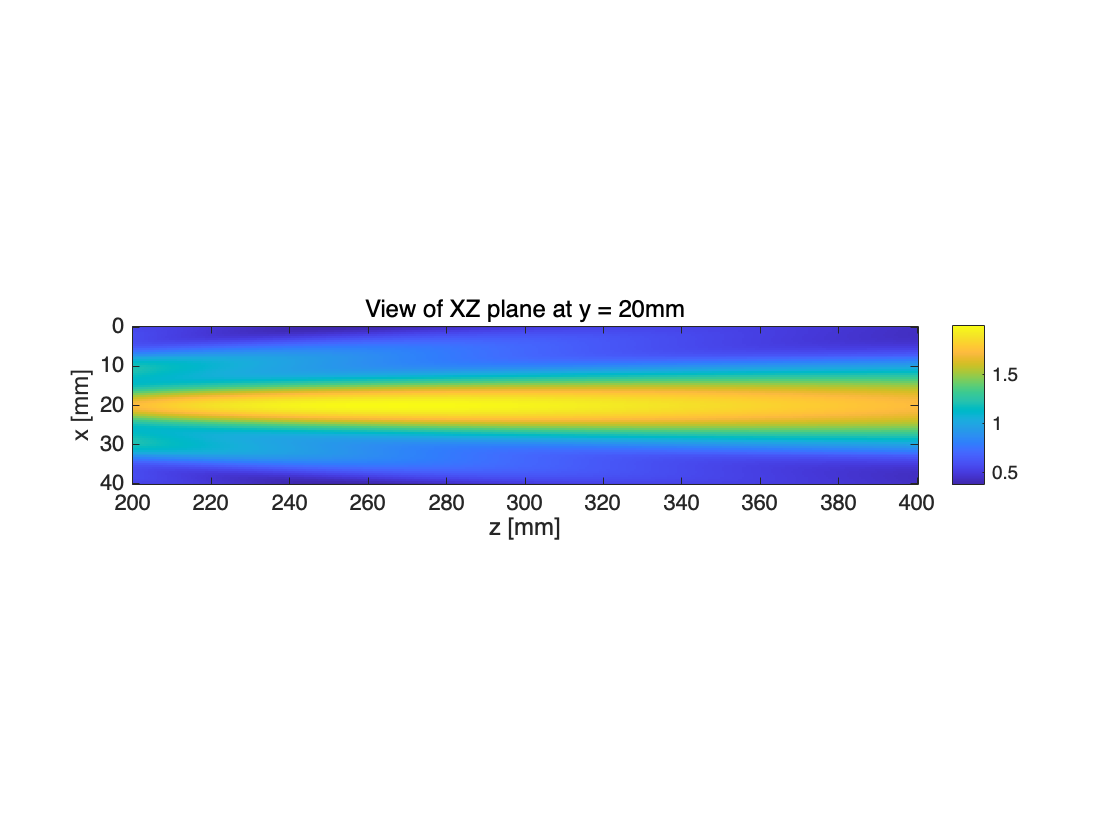


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 20mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');



% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.3);

Started at 2024-05-03 16:03:04
Finished at 2024-05-03 16:03:12
Progressed time : 00:00:07


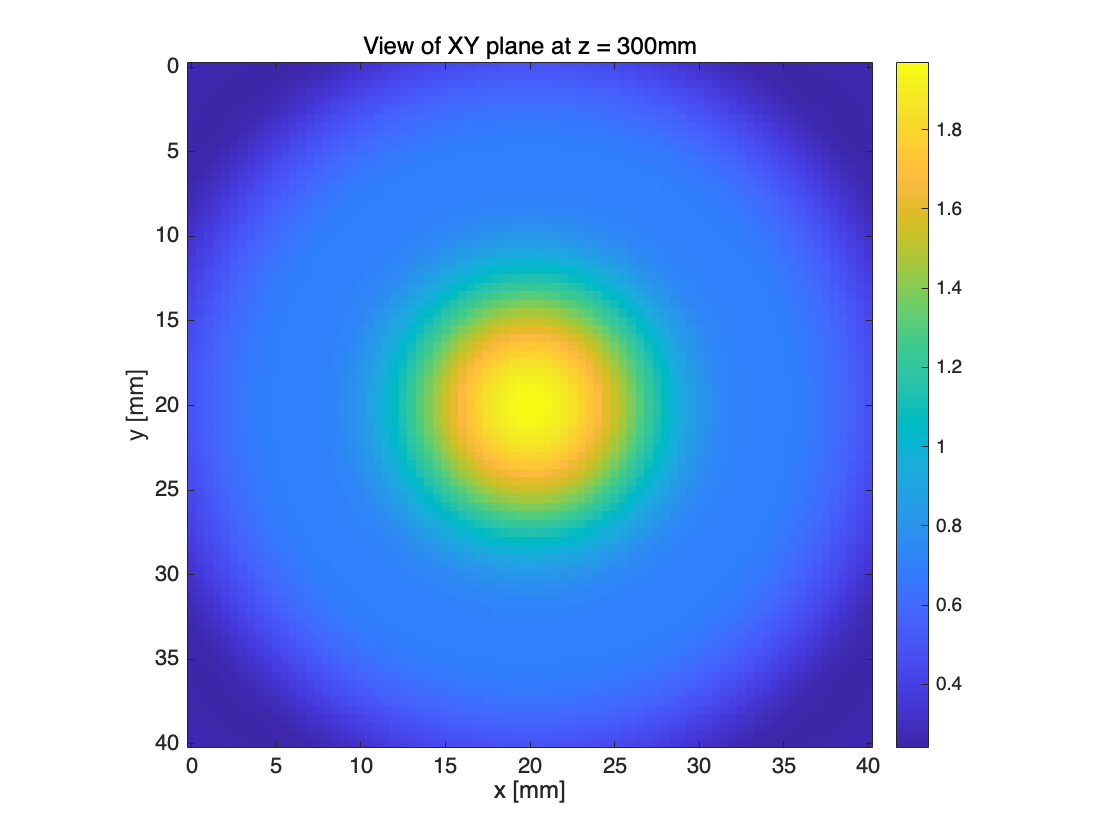


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 300mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');